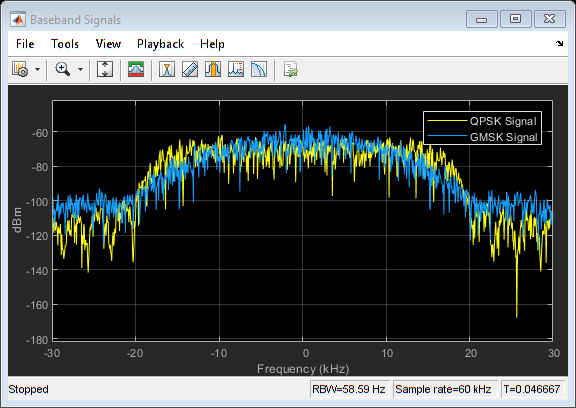

% Number of simulation iterations
nIter = 10;
% Modulation order (QPSK modulation)
M = 4;
% Sample rates
Fs1 = 60e3;
Fs2 = 240e3;
Fs3 = 360e3;

qpskTxFilter = comm.RaisedCosineTransmitFilter('RolloffFactor', 0.3, ...
    'OutputSamplesPerSymbol', 2);

gmskMod = comm.GMSKModulator('BitInput', true', 'SamplesPerSymbol', 2);

% Frequency offset for intra-band contiguous aggregation
sigCombinerCB = SignalAggregator('InterpolationMode', 'Auto', ...
    'FrequencyOffset', [30e3, 90e3], 'SampleRate', Fs1);

% Frequency offset for intra-band non contiguous aggregation
sigCombinerNCB = SignalAggregator('InterpolationMode', 'Auto', ...
    'FrequencyOffset', [30e3, 150e3], 'SampleRate', Fs1);

% Scale factor for scope position
scopeSF = 0.7;
spectrumBB = dsp.SpectrumAnalyzer('Name', 'Baseband Signals', ...
    'NumInputPorts', 2, ...
    'SampleRate', 60e3, 'Method', 'Filter bank', ...
    'AveragingMethod', 'Exponential', 'ShowLegend', true, ...
    'ChannelNames', {'QPSK Signal', 'GMSK Signal'});
spectrumBB.Position = scopeSF * spectrumBB.Position;
spectrumBB.Position(1) = spectrumBB.Position(1) - ...
    spectrumBB.Position(3);

spectrumCB = dsp.SpectrumAnalyzer('Name', 'Intra-Band Contiguous', ...
    'NumInputPorts', 1, ...
    'SampleRate', Fs2, 'Method', 'Filter bank', 'AveragingMethod', 'Exponential');
spectrumCB.Position = scopeSF * spectrumCB.Position;

spectrumNCB = dsp.SpectrumAnalyzer('Name', 'Intra-Band Non-Contiguous', ...
    'NumInputPorts', 1, ...
    'SampleRate', Fs3, 'Method', 'Filter bank', 'AveragingMethod', 'Exponential');
spectrumNCB.Position = scopeSF * spectrumNCB.Position;
spectrumNCB.Position(1) = spectrumNCB.Position(1) + ...
    spectrumNCB.Position(3);

for k=1:nIter

    % Generate QPSK signal
    data = randi([0, M-1], 200, 1);
    modSig = pskmod(data, M, pi/4, 'gray');
    qpskSignal = qpskTxFilter(modSig);

    % Generate GMSK signal
    data = randi([0, 1], 200, 1);
    gmskSignal = gmskMod(data);

    % Visualize the two signals
    spectrumBB(qpskSignal, gmskSignal);

    % Upsample, frequency shift and combine the two signals to model
    % intra-band contiguous carrier aggregation
    combinedSignal = sigCombinerCB([qpskSignal, gmskSignal]);

    % Visualize the resulting signal
    spectrumCB(combinedSignal);

    % Upsample, frequency shift and combine the two signals to model
    % intra-band non contiguous or inter-band non contiguous carrier
    % aggregation
    combinedSignal = sigCombinerNCB([qpskSignal, gmskSignal]);

    % Visualize the resulting signal
    spectrumNCB(combinedSignal);
end

release(spectrumBB);

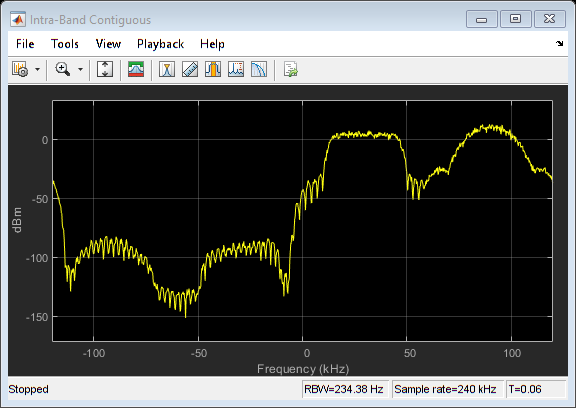

release(spectrumCB);

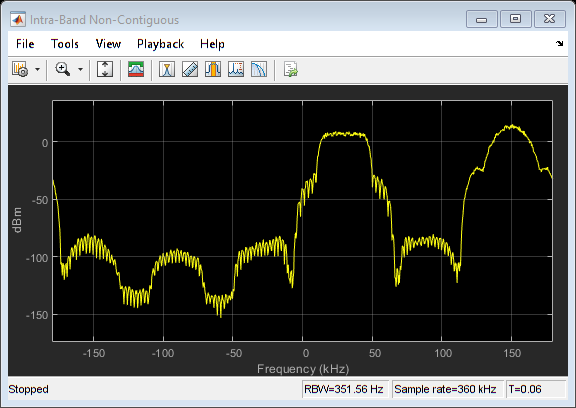

release(spectrumNCB);